# Epoch Cleaning (Optional)

In this livescript, we will further clean the data using epoch cleaning. This part of cleaning is **COMPLETELY OPTIONAL**. We usually do this kind of preprocessing if we have long sections in our experiment where the subject was exposed to an experimental condition. This further cleans our EEG datasets by removing sections of our data that have noise/artifacts.

## What is epoching? 

What is **EEG epoching**? It is a **procedure in which specific time-windows are extracted from continuous EEG signal.** These time windows are called "epochs" and usually are time-locked with respect to an event. We can do some event related potentials analysis, which are brain changes that are time locked to sensory, motor, or cognitive events that provide safe and noninvasive approach to study psychophysiological correlates of mental processes. However, in this case, we are not time locked to any event and are epoching the EEG signal into discrete time windows that can be removed if they have any noise/artifacts. It's a way to further clean your data.  It depends on the type of experiment you are performing. I would not recommend this processing process if you are doing any event related potentials analysis. If you have an experiment where you have large sections of time when the subject is exposed to an experimental condition (e.g. meditation), I would recommend this type of cleaning. I would also recommend using this type of cleaning on baseline data. Please look at the following diagrams: 

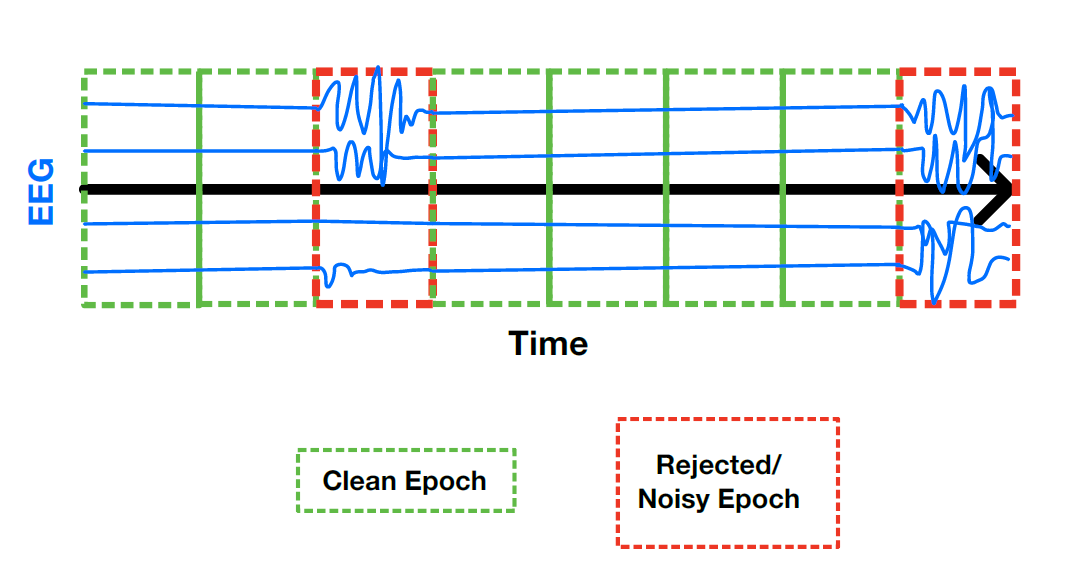

In the above diagram, the blue lines represent (y-axis) represent EEG signals. Each line represents a EEG channel (e.g. O1 or O2). The x-axis represents time, so these are continuous EEG signals. Each dashed box represents an epoch, which I will call "cleaning epochs." The red boxes contain some type of noise/artifact that we do not want to keep as it may affect our results. We can reject these epochs with some EEGLAB functions that we will learn in this tutorial. Notice that sometimes the noise/artifacts can only be present in some channels or all channels. When we reject these epochs, we remove all channel data for that epoch. Moreover, we reduce our data (e.g. if these were 1 second epochs, we would remove 2 seconds of our data). You should be cognizant in how much of your data you are rejecting; a good guideline is to never remove more than 10% of your total data when epoch cleaning. Also notice that we epoch across all data. 

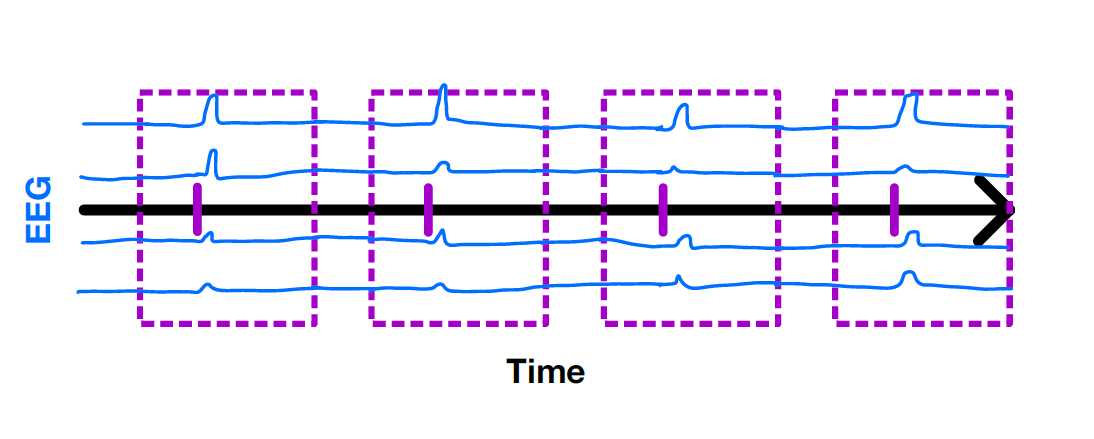

In the above diagram, the blue lines represent (y-axis) EEG signals.Each line represents a EEG channel (e.g. O1 or O2). The x-axis represents time, so these are continuous EEG signals. Each violet box represents an epoch, which we will call "event epochs." The violet short line represent some type of stimuli (e.g. visual, audio, etc) that occurs (i.e. an event marker). If we want to see how the brain responds to a specific event, we epoch a little before and after the event (e.g. 100 ms before and 500 ms after the event). We have to make sure these epochs do not overlap. While it may not be as obvious as this simplified diagram, we might see a response (the bump in the EEG signal after the event) across the channels; this is a brain response that we may want to concentrate on analyzing as it propogates across all channels (or a few channels). For event related potential analysis, we usually plot an average potential across all epochs/trials in one channel. For instance, if the event was a visual stimuli, we may plot the average event related potential across the occipital channels (O1 or O2). We will cover this type of analysis later, but I thought you should know the difference between the two types of epoching. One is for cleaning and the other is for analysis.

Before we get started, let's load in our clean EEG data from the last tutorial (ASR/ICA). We begin with two familiar code blocks: 

%% Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
eeglab;

         You may experience errors if a plugin overloads a MATLAB function
eeglab: options file is C:\Users\enriq\eeg_options.m


%Directory where are data are located: 
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located: 
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located: 
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data: 
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

data\set already exists!

Let's load our clean EEG data: 

%Format specifier for our recording: 
file_spec = 'vrcct_%s_%s_%s.%s'; %Four char formatting operators

%Let us define the name parts of our file: 
sub = 'p16'; %subject or participant 16
study = 'prestudy'; %First session of experiment
part = 'condition_clean'; %clean meditation part of session
ext = 'set'; %File extension of our dataset (Set file)

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Loading Set file
EEG = pop_loadset( ...
    'filename',file_name, ...
    'filepath',dir_set);

pop_loadset(): loading file data\set\vrcct_p16_prestudy_condition_clean.set ...
Reading float file 'data\set\vrcct_p16_prestudy_condition_clean.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## Epoching EEG

Epoching EEG is very simple and can be performed with one function: **eeg_regepochs**. There are two inputs. The first is the EEG struct and the second is the 'recurrence' input which is the length of the epochs (defaults to 1 second). The output is the epoched EEG struct. Let's perform it: 

%Epoching EEG
EEG = eeg_regepochs(EEG,'recurrence',1); 

The input dataset will be split into 646 epochs of 1 s
Inserting 646 type 'X' events: .......................................40
.......................................80..............................
.........120.......................................160....................
...................200.......................................240..........
.............................280.......................................320
.......................................360..............................
.........400.......................................440....................
...................480.......................................520..........
.............................560.......................................600
.......................................640......
Sorting the event table.
Splitting the data into 646 1.00-s epochs
pop_epoch():646 epochs selected
Epoching...
pop_epoch():646 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs

What does our EEG struct look like now? Well we have separated the data into 1 second epochs. We have a sampling rate of 250 Hz, so we can expect each of our epochs should have 250 data points. For this particular dataset, we have 59 channels. We also have a new field called trials (i.e. epochs) that gives us the number of epochs in our epoched EEG dataset. Therefore, our data should be 3-dimensional array of size 59 channels x 250 data points x 646 epochs. Also notice that our xmin and xmax (time limits of each epochs) have changed to 0 and 0.9960, respectively. This is also reflected in the times field. Run and review the following code block: 

% Number of Epochs/Trials
fprintf('The number of 1 second epochs in our EEG is %i',EEG.trials);

The number of 1 second epochs in our EEG is 646


% Number of data points for each epoch
fprintf('The number of data points in each epoch is %i',EEG.pnts);

The number of data points in each epoch is 250


% Size of our EEG data array: 
fprintf( ...
    'The epoched EEG data has %i channels, %i data points in each epoch, and %i epochs', ...
    size(EEG.data,1),size(EEG.data,2),size(EEG.data,3));

The epoched EEG data has 59 channels, 250 data points in each epoch, and 646 epochs

## Abnormal/Extreme EEG Value Epoch Cleaning

**Abnormal/Extreme EEG values** is a criteria we can use to reject epochs. For instance, when we clench our jaws, it may cause some your EEG signals to distort like below (in red): 

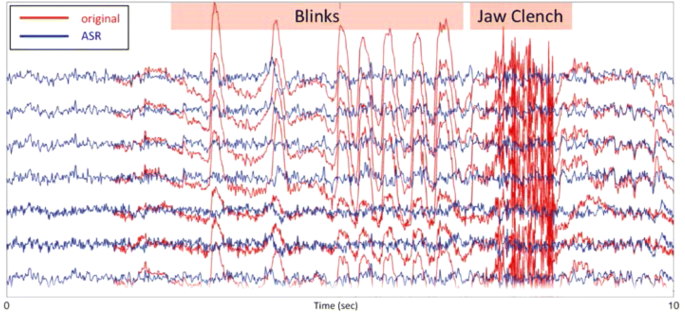

The EEGLAB function we use is called **pop_eegthresh**. This function takes in several inputs (from documentation): 

- **INEEG**: EEG struct you want to epoch clean

- **typerej**: Type of rejection you want to perform. If you want to reject independent components (calculated via ICA), the input should be 0. If you want to reject EEG channels, the input should be 1. (Default: 1)

- **elec_comp**: electrode/component indices to take into consideration for rejection

- **lowthresh**: Lower threshold limit in microvolts (for channels) or standard deviation (for individual components). 

- **upthresh**: Upper threshold limit in microvolts (for channels) or standard deviation (for individual components).

- **starttime**: rejection window start time (s) in seconds. We fill this in as 0.

- **endtime**: rejection window end time (s) in seconds. If each epoch is 1 second long, then this input would be 1.0. If each epoch is 2 seconds long, this this input would be 2.0.

- **superpose**: A parameter for plotting via the GUI display. An input of 0 does not superpose rejection markings on previous rejection marks stored in the dataset. An input of 1 show both current and previously marked rejections using different colors (Default: 0)

- **reject**: A parameter to reject data immediately. An input of 0 does not reject the marked epochs/trials, and stores the marks. An input of 1 immediately reject marked epochs/trials. (Default: 1)

The output should be an EEG struct with or without marked epochs that have abnormal values. This EEG struct will have a new field name called **reject** and within the field, we have a field name **rejthresh** that stores a boolean array that marks which epochs/trials to reject. 

One caveat to this type of epoch cleaning is **what threshold should you use**. This threshold can change with the type of EEG headset used or subject characteristics. For instance, a subject with long hair may not have good contact to the nodes, so EEG signals may have a lower amplitude. I have seen a threshold of -500 to 500 microvolts in [**Makoto's Preprocessing Pipeline**](https://sccn.ucsd.edu/wiki/Makoto's_preprocessing_pipeline#Epoch_data_to_-1_to_2_sec_.2809.2F11.2F2019_updated.29) to account for eye blinks. You can refer to that resource for a lot of things, so I would recommend you look at it. Since eye blinks may appear often in data, rejecting epochs with eye blinks may reject a lot of our data (even though we might have eliminated as many eye blink artifacts with ASR and ICA). Another way to avoid lots of epoch rejection through eye blinks is to not include the frontal channels (see below; those channels closer to the eyes that have the most prominent eye blink artifacts) in the pop_eegthresh function (look at the elec_comp input). 

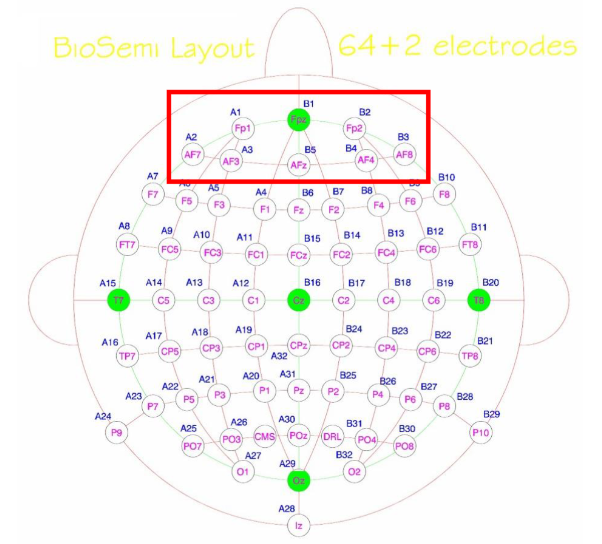

% Frontal Channels to exlude in Epoch Cleaning via Abnormal Values
frontal_channels = {'Fp1','Fpz','Fp2','AF7','AF3','AFz','AF4','AF8'};

%All channels indices that are not frontal channels
% For this we use ismember which takes in two cell arrays and returns an
% array of the size of the first array containing true where elements of A
% are in B and false otherwise (boolean array); then we use find to get
% the indices where True is. The tilda (~) is a not operator
elec_comp = find(~ismember({EEG.chanlocs.labels},frontal_channels));

%Other Inputs for our pop_eegthresh: 
typerej = 1; %Electrode/Channel rejection
lowThresh = -500; %uV
upThresh = 500; %uV
startTime = 0; %Seconds
endTime = 1.0; %Seconds
superPose = 1; %Plot with different color
reject = 0; % Do not reject immediately


% Removing epochs that have extreme/abnormal values (exlcluding frontal
% channels): 
EEG = pop_eegthresh( ...
    EEG,typerej,elec_comp, ...
    lowThresh,upThresh, ...
    startTime,endTime, ...
    superPose,reject);

51 channel selected
0/646 trials marked for rejection


As we have seen with the output, we marked 0 epochs for rejection. This is okay, but perhaps our threshold is too high. We might want to visualize it to see if there isn't any large noise/artifacts. 

## **Improbable (Joint Probability) EEG Data Epoch Cleaning**

We can also reject epochs using **joint probability **of the recorded electrode or component activities observed at each time point. That is, if we observe large absolute values at most electrodes (which is improbable) at a certain time point, we mark the epoch for rejection.

The EEGLAB function we use is called **pop_jointprob**. This function takes in several inputs (from documentation): 

- **INEEG**: EEG struct you want to epoch clean

- **typerej**: Type of rejection you want to perform. If you want to reject independent components (calculated via ICA), the input should be 0. If you want to reject EEG channels, the input should be 1. (Default: 1)

- **elec_comp**: electrode/component indices to take into consideration for rejection

- **locthresh**: Lower threshold limit in standard deviation units. This represents activity probability limit(s) in a single channel 

- **globthresh**: Upper threshold limit in or standard deviation units. This represents all activity probability limit(s) for all channels

- **superpose**: A parameter for plotting via the GUI display. An input of 0 does not superpose rejection markings on previous rejection marks stored in the dataset. An input of 1 show both current and previously marked rejections using different colors (Default: 0)

- **reject**: A parameter to reject data immediately. An input of 0 does not reject the marked epochs/trials, and stores the marks. An input of 1 immediately reject marked epochs/trials. (Default: 1)

- **vistype**: Visualization type. An input of 0 calls rejstatepoch() and an input of 1 calls eegplot. (Default: 0)

- **topcommand**: deprecated argument, but is kept to ensure backward compatibility. (We will have this be an empty array [])

- **plotflag**: An input of 1 plots the data and an input of 0 does not plot the data

The output should be an EEG struct with or without marked epochs that have improbable values. This EEG struct will have a new field name called **reject** and within the field, we have a field name **rejjp** that stores a boolean array that marks which epochs/trials to reject. 

The threshold for this part is again provided in Makoto's pipeline (see link above): 6 SD for the local threshold and 2 SD for the global threshold. Let's use this function: 

%Other Inputs for our pop_eegthresh: 
typerej = 1; %Electrode/Channel rejection
elec_comp = 1:EEG.nbchan; % We use all channels
localThresh = 6; %single channel threshold of 6 SD
globalThresh = 2; %all channel threshold of 2 SD
superPose = 1; %Plot with different color
reject = 0; % Do not reject immediately
visType = 0; %plot type but don't use
topCommand = [];
plotFlag = 0; % No plotting yet

%Eliminating EEG data using improbability test:
EEG = pop_jointprob( ...
    EEG, ...
    typerej, elec_comp, ...
    localThresh,globalThresh, ...
    superPose,reject, ...
    visType,topCommand, ...
    plotFlag);

Computing joint probability for channels...
Computing all-channel probability...
56/646 trials marked for rejection
56 trials marked for rejection


From our epoch cleaning, we have marked a total of 57 trials (only from our improbable value epoch cleaning) or 8.9% of our data (100*57/646) which is within reason (aim for less than 10% rejection rate). 

## Visualizing our Marked Epochs Before Rejecting Them

**These next few lines of code can be copied and pasted if you want to visualize marked epochs (given that you loaded in the data as EEG).** There are alot of new functions that we would not use unless you want to check your data, so don't be intimidated by it; just know that it is there to plot. The epochs that were marked by the abnormal/extreme value epoch cleaning is color coded in a Yellow-Green color, but we didn't mark any epochs, so you won't see this color. The epochs that were marked by joint probability epoch cleaning is color coded in Red and will see 57 epochs marked. Scroll through the data. Did you notice that the data is divided into 1 second epochs (like in the earlier diagram)?

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


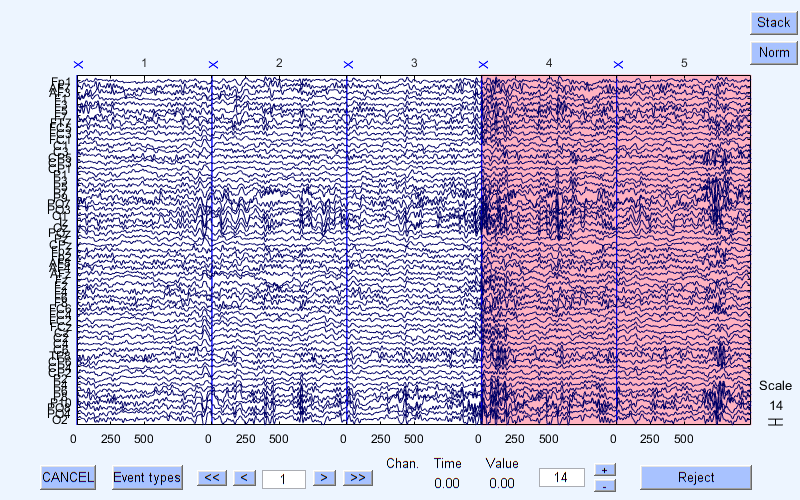


ans =

     []



%Command input for plotting
cmd = [ ...
    '[tmprej tmprejE] = eegplot2trialMod( TMPREJ,' num2str(EEG.pnts) ',' num2str(EEG.trials) ');' ...
    'EEG = pop_rejepoch(EEG, tmprej, 1);' ...
    'detectArtefactsFinished=1;' ...
    ] ;

%Plotting parameters for abnormal/extreme EEG values (Yellow-Green):
plotRejTre = trial2eegplot( ...
    EEG.reject.rejthresh, ...
    EEG.reject.rejthreshE, ...
    EEG.pnts, ...
    EEG.reject.rejthreshcol);

%Plotting parameters for improbable (joint probability) epoch cleaning (Red):
plotRejJp = trial2eegplot( ...
    EEG.reject.rejjp, ...
    EEG.reject.rejjpE, ...
    EEG.pnts, ...
    EEG.reject.rejjpcol);

%% Plotting data and artifacts:
rejE = [plotRejTre;plotRejJp];

%Plotting   
eegplot( ...
    EEG.data, ...
    'srate',EEG.srate, ...
    'events',EEG.event, ...
    'eloc_file',EEG.chanlocs, ...
    'winrej',rejE, ...
    'command',cmd, ...
    'butlabel','Reject')

## Rejecting Epochs with Noise/Artifacts

Finally, we can reject all marked epochs using the **pop_rejepoch** function that takes in an EEG struct, the indices of marked epochs, and a confirm input (used to display rejects and ask for confirmation). 

% Getting the boolean arrays of marked indices; we use an or (|) operator
% include any epoch marked by abnormal epoch cleaning or joint probability
% epoch cleaning. Then we use find to find the indices of the marked epochs
boolean_array = EEG.reject.rejthresh | EEG.reject.rejjp;
mark_indices = find(boolean_array);

%Confirmation input: 
confirm = 0; % we do not want any confirmation prompt

%Finally rejecting the marked epochs!
EEG = pop_rejepoch( ...
    EEG, mark_indices,confirm);

56/646 trials rejected
Removing 56 trial(s)...
Pop_select: removing 56 unreferenced events


## Saving our Epoch Cleaned Dataset

%Changing name to clean
part = 'condition_epochClean';

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Saving our dataset (overwriting the set file): 
EEG = pop_saveset( ...
    EEG, ...
    'filename',file_name, ...
    'filepath',dir_set, ...
    'savemode','twofiles');

Saving dataset...


Sometimes though, we may want to transform the epoched data into a continuous dataset. This may make downstream analysis easier and convenient. To convert epoched data into continuous data (without the noisy epochs), we use the function **eeg_epoch2continuous **function. Using it is pretty self-explanatory: 

% Epoched to Continuous
EEG_cont = eeg_epoch2continuous(EEG)

%Changing name to clean
part = 'condition_epochClean_continuous';

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Saving our dataset (overwriting the set file): 
EEG = pop_saveset( ...
    EEG_cont, ...
    'filename',file_name, ...
    'filepath',dir_set, ...
    'savemode','twofiles');

## Conclusion

We have epoch cleaned using two criteria: abnormal/extreme values and improbable data. These are optional cleaning processes. I recommend use these on baseline datasets to clean your baseline as much as possible and datasets that have long experimental periods. These are the two type of epoch cleaning, but there are others like finding abnormal trends using correlation coefficients or finding abnormal distributions or finding abnormal spectra (see below of EEGLAB GUI interface of epoch cleaning). I haven't used any of them, so I don't have any experience in what they do. Each lab has different criteria and pipelines to clean EEG data, so it is better to consult your PI or other more experienced computational neuroscientist to help you in cleaning. 

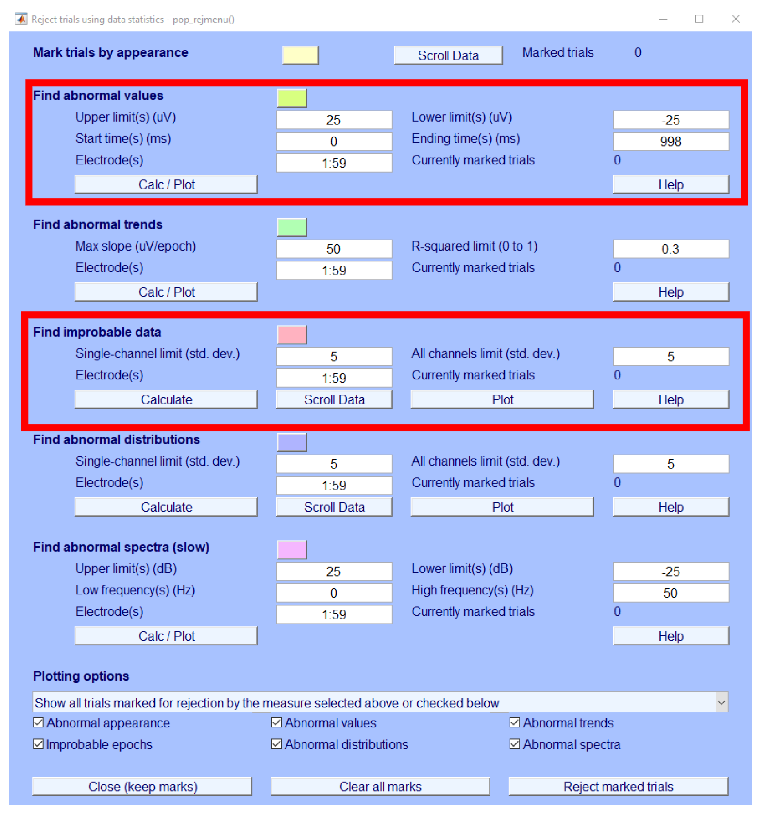

The next tutorial will be an interactive exercise to create a user-defined function that will clean your data using all preprocessing techniques we used so far (with the exception of epoch cleaning). 